clear all
data=readtable("C:\Users\thoma\Downloads\book1.xlsx")

data = 8294×3 table
       Date       PX_LAST    TOT_RETURN_INDEX_GROSS_DVDS
    __________    _______    ___________________________

           NaT    3320.3               6843.8           
    28/02/2019    3298.3               6798.3           
    27/02/2019    3282.8               6766.4           
    26/02/2019    3289.3               6779.9           
    25/02/2019      3280               6760.7           
    22/02/2019    3270.6               6741.2           
    21/02/2019    3263.7               6727.1           
    20/02/2019    3259.5               6718.4           
    19/02/2019    3239.4                 6677           
    18/02/2019    3244.8               6688.1           
    15/02/2019    3241.3               6680.8           
    14/02/2019    3182.7                 6560           
    13/02/2019    3202.4                 6599           
    12/02/2019    3190

data=flipud(data)

data = 8294×3 table
       Date       PX_LAST    TOT_RETURN_INDEX_GROSS_DVDS
    __________    _______    ___________________________

    31/12/1986    900.82               900.82           
    01/01/1987    900.82               900.82           
    02/01/1987    891.78               891.78           
    05/01/1987    898.33               898.33           
    06/01/1987    902.32               902.32           
    07/01/1987    899.15               899.15           
    08/01/1987    887.37               887.37           
    09/01/1987    868.31               868.31           
    12/01/1987    879.41               879.41           
    13/01/1987    872.74               872.74           
    14/01/1987    876.39               876.39           
    15/01/1987    884.37               884.37           
    16/01/1987    883.78               883.78           
    19/01/1987    876.

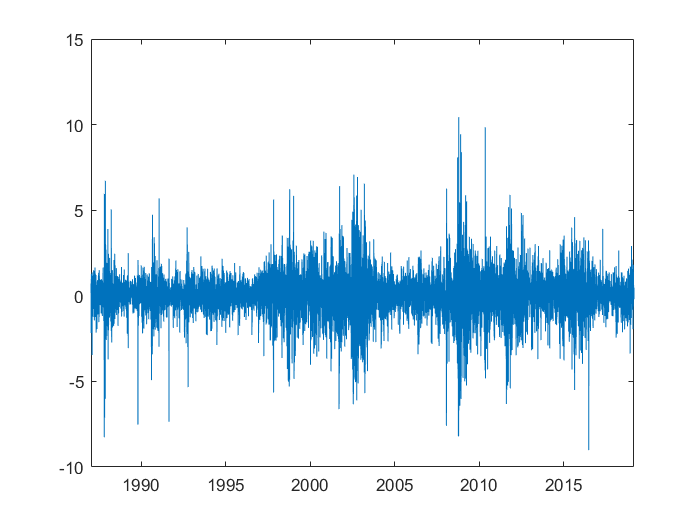


dates=datetime(data.Date(2:end),'Convertfrom','excel');

logreturn=100*diff(log(data.PX_LAST(2:end)));
plot(dates(3:end),logreturn(2:end))


logreturn

logreturn =    -1.0086
    0.7318
    0.4432
   -0.3519
   -1.3188
   -2.1713
    1.2702
   -0.7614
    0.4174
    0.9064


initialvalues = [1,1,.05,0.7,.9, 0]

initialvalues =     1.0000    1.0000    0.0500    0.7000    0.9000         0


Ovenfor=[inf inf 1 inf inf inf]

Ovenfor =    Inf   Inf     1   Inf   Inf   Inf


Nedenfor=[0 0 -1 0 0 0]

Nedenfor =      0     0    -1     0     0     0


T=size(logreturn,1)

T = 8292

w = .06*.94.^(0:T-2); 
backCast= w*logreturn(2:end).^2;
options = optimset('fmincon'); 
options.Display = 'iter'; 
options.Algorithm = 'sqp'; 
estimates = fmincon(@APGARCHco,initialvalues,[],[],[],[],Nedenfor,Ovenfor,@nlc,options,logreturn(2:1500),backCast);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7    5.258324e+03     9.636e-01     1.000e+00     0.000e+00     1.490e+04  
Objective function returned NaN; trying a new point...
    1          15    2.027734e+03     2.575e+00     7.000e-01     4.635e+00     1.572e+05  
Nonlinear constraint function returned complex; trying a new point...
    2          25    1.997328e+03     0.000e+00     3.430e-01     3.136e+00     3.309e+04  
Objective function returned NaN; trying a new point...
    3          35    1.991488e+03     0.000e+00     3.430e-01     9.424e-01     3.106e+04  
Nonlinear constraint function returned complex; trying a new point...
    4          60    1.991266e+03     0.000e+00     1.628e-03     2.898e-02     3.073e+04  
    5          69    1.988003e+03     0.000e+00     4.900e-01     8.284e-01     2.790e+04  
    6          8

initialvalues2=estimates

initialvalues2 =     7.6632    0.0838    0.2390    0.0622    0.2561    1.0531


[estimates,fval, exitflag,output,lambda,gradient,hessian] = fmincon(@APGARCHco,initialvalues2,[],[],[],[],Nedenfor,Ovenfor,@nlc,options,logreturn(2:end),backCast);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7    1.276981e+04     0.000e+00     1.000e+00     0.000e+00     1.821e+03  
Nonlinear constraint function returned complex; trying a new point...
    1          38    1.275039e+04     0.000e+00     1.916e-04     2.525e-01     7.625e+02  
Nonlinear constraint function returned complex; trying a new point...
    2          50    1.269802e+04     0.000e+00     1.681e-01     1.334e+00     5.395e+02  
    3          59    1.269040e+04     0.000e+00     4.900e-01     9.627e-01     4.767e+03  
    4          70    1.266632e+04     0.000e+00     2.401e-01     6.492e-01     1.386e+03  
Objective function returned Inf; trying a new point...
    5          81    1.262124e+04     0.000e+00     2.401e-01     1.616e+00     5.675e+03  
Nonlinear constraint function returned complex; trying a new point...
 

[ll,lls,h,z]=APGARCHco(estimates,logreturn(2:end),backCast);
 standardfejl=z./sqrt(h)

standardfejl =     0.0000
    0.4555
   -0.3792
   -1.4221
   -2.0517
    0.9818
   -0.6148
    0.3290
    0.7562
   -0.0583


 mean(standardfejl)

ans = 0.0174

mean(standardfejl.^2)

ans = 1.0008

mean(standardfejl.^3)

ans = -0.5282

mean(standardfejl.^4)

ans = 7.9262

% [h,pValue,stat,cValue]=lbqtest(standardfejl,'lags',5)
% [h,pValue,stat,cValue]=lbqtest(standardfejl.^2,'lags',4)

% 
 ll

ll = 1.2270e+04

 lls

lls =     0.9498
    0.9952
    0.9162
    1.8547
    3.0803
    1.6585
    1.3218
    1.2109
    1.3861
    1.0553


 fval

fval = 1.2270e+04

 h

h =     1.0636
    0.9465
    0.8612
    0.8600
    1.1200
    1.6740
    1.5337
    1.6091
    1.4369
    1.3091


 exitflag

exitflag = 2

 output

output = struct with fields:
         iterations: 35
          funcCount: 389
          algorithm: 'sqp'
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the default value of the step size tolerance and constraints are ↵satisfied to within the selected value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵Optimization Metric                                           Options↵max(abs(delta_x./x)) =   8.62e-07                       StepTolerance =   1e-06 (default)↵relative max(constraint violation) =   0.00e+00   ConstraintTolerance =   1e-06 (selected)'
    constrviolation: 0
           stepsize: 1.0564e-06
       lssteplength: 1.5778e-05
      firstorde

 lambda

lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: [0×1 double]
       ineqlin: [0×1 double]
    ineqnonlin: 95.2818
         lower: [6×1 double]
         upper: [6×1 double]


 gradient

gradient =    -5.1881
 -100.3040
    0.0530
    0.0092
  -95.2924
   -0.0012


 hessian

hessian = 	1.0e+06 *

    0.0060    0.0118    0.0024    0.0466    0.0325   -0.0001
    0.0118    2.4093   -0.0294    3.0888    3.1654   -0.0035
    0.0024   -0.0294    0.0112   -0.0252   -0.0537   -0.0004
    0.0466    3.0888   -0.0252    4.5562    4.3951   -0.0044
    0.0325    3.1654   -0.0537    4.3951    4.4391   -0.0035
   -0.0001   -0.0035   -0.0004   -0.0044   -0.0035    0.0000


 eig(hessian)

ans = 	1.0e+07 *

    0.0000
    0.0003
    0.0006
    0.0059
    0.0219
    1.1135


 delta=estimates(:,1)

delta = 0.9847

alpha=estimates(:,2)

alpha = 0.0778

gamma=estimates(:,3)

gamma = 0.7585

omega=estimates(:,4)

omega = 0.0269

beta=estimates(:,5)

beta = 0.9181

lambda1=estimates(:,6)

lambda1 = 1.2252



% varians 
forskel=0.00001*estimates

forskel = 	1.0e+-4 *

    0.0985    0.0078    0.0759    0.0027    0.0918    0.1225


antal=length(estimates)

antal = 6

bidrag=zeros(T-1,antal);
for i=1:antal
    j=forskel(i);
    delta=zeros(1,antal);
    delta(i)=j;
    [~, loglikelidtover]= APGARCHco(estimates+delta,logreturn(2:end),backCast);
    [~, loglikelidtunder]=APGARCHco(estimates-delta,logreturn(2:end),backCast);
    bidrag(:,i)=(loglikelidtover-loglikelidtunder)/(2*j)
    %     J_i=bidrag(i)*bidrag(i)'
end

bidrag =          0         0         0         0         0         0
    0.0463         0         0         0         0         0
    0.0720         0         0         0         0         0
   -0.0600         0         0         0         0         0
   -0.2308         0         0         0         0         0
    0.0052         0         0         0         0         0
    0.0916         0         0         0         0         0
    0.0977         0         0         0         0         0
    0.0603         0         0         0         0         0
    0.1515         0         0         0         0         0


bidrag =          0         0         0         0         0         0
    0.0463    0.0000         0         0         0         0
    0.0720    0.1036         0         0         0         0
   -0.0600   -0.8111         0         0         0         0
   -0.2308   -9.1093         0         0         0         0
    0.0052    0.1839         0         0         0         0
    0.0916    3.1922         0         0         0         0
    0.0977    5.0585         0         0         0         0
    0.0603    2.3959         0         0         0         0
    0.1515    5.5580         0         0         0         0


bidrag =          0         0         0         0         0         0
    0.0463    0.0000   -0.0000         0         0         0
    0.0720    0.1036   -0.0329         0         0         0
   -0.0600   -0.8111    0.0057         0         0         0
   -0.2308   -9.1093   -0.2930         0         0         0
    0.0052    0.1839    0.0071         0         0         0
    0.0916    3.1922    0.0669         0         0         0
    0.0977    5.0585    0.1276         0         0         0
    0.0603    2.3959    0.0474         0         0         0
    0.1515    5.5580    0.0430         0         0         0


bidrag = 	1.0e+03 *

         0         0         0         0         0         0
    0.0000    0.0000   -0.0000    0.0008         0         0
    0.0001    0.0001   -0.0000    0.0018         0         0
   -0.0001   -0.0008    0.0000   -0.0031         0         0
   -0.0002   -0.0091   -0.0003   -0.0109         0         0
    0.0000    0.0002    0.0000    0.0001         0         0
    0.0001    0.0032    0.0001    0.0025         0         0
    0.0001    0.0051    0.0001    0.0039         0         0
    0.0001    0.0024    0.0000    0.0022         0         0
    0.0002    0.0056    0.0000    0.0058         0         0


bidrag = 	1.0e+03 *

         0         0         0         0         0         0
    0.0000    0.0000   -0.0000    0.0008    0.0009         0
    0.0001    0.0001   -0.0000    0.0018    0.0018         0
   -0.0001   -0.0008    0.0000   -0.0031   -0.0030         0
   -0.0002   -0.0091   -0.0003   -0.0109   -0.0105         0
    0.0000    0.0002    0.0000    0.0001    0.0001         0
    0.0001    0.0032    0.0001    0.0025    0.0026         0
    0.0001    0.0051    0.0001    0.0039    0.0043         0
    0.0001    0.0024    0.0000    0.0022    0.0024         0
    0.0002    0.0056    0.0000    0.0058    0.0065         0


bidrag = 	1.0e+03 *

         0         0         0         0         0   -0.0000
    0.0000    0.0000   -0.0000    0.0008    0.0009    0.0001
    0.0001    0.0001   -0.0000    0.0018    0.0018    0.0001
   -0.0001   -0.0008    0.0000   -0.0031   -0.0030   -0.0001
   -0.0002   -0.0091   -0.0003   -0.0109   -0.0105   -0.0002
    0.0000    0.0002    0.0000    0.0001    0.0001    0.0000
    0.0001    0.0032    0.0001    0.0025    0.0026    0.0000
    0.0001    0.0051    0.0001    0.0039    0.0043    0.0000
    0.0001    0.0024    0.0000    0.0022    0.0024    0.0000
    0.0002    0.0056    0.0000    0.0058    0.0065    0.0000


mean(bidrag)

ans =    -0.0006   -0.0121    0.0000   -0.0000   -0.0115    0.0000


I=bidrag'*bidrag/T

I = 	1.0e+03 *

    0.0004    0.0112   -0.0001    0.0238    0.0202    0.0000
    0.0112    0.4166   -0.0034    0.7777    0.6815    0.0000
   -0.0001   -0.0034    0.0002   -0.0108   -0.0090    0.0000
    0.0238    0.7777   -0.0108    1.8727    1.4913    0.0000
    0.0202    0.6815   -0.0090    1.4913    1.2511    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


% Så skal J findes
J=hessian_beggesider(@APGARCHco, estimates, logreturn(2:end), backCast)

afledtep =      0
     0
     0
     0
     0
     0


afledten =      0
     0
     0
     0
     0
     0


J = 	1.0e+06 *

    0.0010    0.0331   -0.0002    0.0451    0.0477    0.0000
    0.0331    1.3032   -0.0069    1.6906    1.8158    0.0000
   -0.0002   -0.0069    0.0008   -0.0239   -0.0186    0.0000
    0.0451    1.6906   -0.0239    2.9343    2.7036    0.0000
    0.0477    1.8158   -0.0186    2.7036    2.7341    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000


J=J/T

J =     0.1242    3.9904   -0.0234    5.4348    5.7488    0.0000
    3.9904  157.1626   -0.8367  203.8797  218.9853    0.0009
   -0.0234   -0.8367    0.1005   -2.8822   -2.2401    0.0000
    5.4348  203.8797   -2.8822  353.8737  326.0460    0.0012
    5.7488  218.9853   -2.2401  326.0460  329.7282    0.0013
    0.0000    0.0009    0.0000    0.0012    0.0013   -0.0006


Jinv=J\eye(length(J))

Jinv = 	1.0e+03 *

    0.0489   -0.0002   -0.0062    0.0002   -0.0010   -0.0009
   -0.0002    0.0002   -0.0012    0.0001   -0.0002   -0.0000
   -0.0062   -0.0012    0.0211   -0.0001    0.0011    0.0009
    0.0002    0.0001   -0.0001    0.0001   -0.0001   -0.0000
   -0.0010   -0.0002    0.0011   -0.0001    0.0003    0.0001
   -0.0009   -0.0000    0.0009   -0.0000    0.0001   -1.7728


hessian\eye((length(hessian)))

ans = 	1.0e+03 *

    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0007
    0.0000    0.0001    0.0002    0.0000   -0.0001    0.0095
    0.0000    0.0002    0.0009    0.0001   -0.0002    0.0365
    0.0000    0.0000    0.0001    0.0000   -0.0000    0.0043
   -0.0000   -0.0001   -0.0002   -0.0000    0.0001   -0.0095
    0.0007    0.0095    0.0365    0.0043   -0.0095    1.4603


% 

% % Så kombineres J og I for at få variansen 
var=Jinv*I*Jinv/T

var =     0.0089   -0.0002   -0.0016   -0.0000   -0.0000   -0.0001
   -0.0002    0.0002   -0.0007    0.0000   -0.0001   -0.0000
   -0.0016   -0.0007    0.0099    0.0002    0.0005    0.0004
   -0.0000    0.0000    0.0002    0.0000   -0.0000    0.0000
   -0.0000   -0.0001    0.0005   -0.0000    0.0001    0.0000
   -0.0001   -0.0000    0.0004    0.0000    0.0000    0.0032


se=sqrt(diag(var))

se =     0.0944
    0.0123
    0.0995
    0.0054
    0.0118
    0.0561


% estimates
% 
% % simulation og test af modellen
% 
% name={'delta';'alpha';'gamma';'omega';'e';'beta'};

delta=estimates(:,1)

delta = 0.9847

alpha=estimates(:,2)

alpha = 0.0778

gamma=estimates(:,3)

gamma = 0.7585

omega=estimates(:,4)/10000

omega = 2.6911e-06

beta=estimates(:,5)

beta = 0.9181

lambda1=estimates(:,6)

lambda1 = 1.2252



standardafvigelse=(se')

standardafvigelse =     0.0944    0.0123    0.0995    0.0054    0.0118    0.0561




s=rng;
tilfaeldige=trnd(8294,121,10000);
sigma2=zeros(121,10000);
y=zeros(121,10000);
S=zeros(121,10000);
r=zeros(121,10000);
r(1,:)=0;
S(1,:)=1;
theta(1,:)=0

theta = 0

K=1

K = 1

sigma2(1,:)=h(end)/10000

sigma2 = 	1.0e+-4 *

    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269    0.4269
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        


for j=1:10000
for i=2:120
    sigma2(i,j)=(omega + alpha*(abs(tilfaeldige(i-1,j)*sqrt(sigma2(i-1,j))))^delta+beta*sigma2(i-1,j)^(delta/2))^(2/delta);
    y(i,j)=sqrt(sigma2(i,j))*tilfaeldige(i,j)+(0.003/251)/10000-sigma2(i-1,j)/2;
    r(i,j)=y(i,j)+r(i-1,j);
    S(i,j)=exp(r(i,j));
    
end
end
y

y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0087   -0.0103    0.0004    0.0018   -0.0033   -0.0045    0.0036   -0.0020   -0.0015   -0.0030    0.0059   -0.0012   -0.0005   -0.0046    0.0012   -0.0143    0.0101    0.0121   -0.0059    0.0074    0.0033    0.0021   -0.0011    0.0066    0.0032    0.0020   -0.0010    0.0003    0.0008    0.0085    0.0063    0.0060   -0.0024   -0.0009   -0.0093    0.0103   -0.0062   -0.0033    0.0099   -0.0073    0.0047   -0.0089    0.0081   -0.0082    0.0210   -0.0012   -0.0058    0.0062    0.0066   -0

r

r =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0087   -0.0103    0.0004    0.0018   -0.0033   -0.0045    0.0036   -0.0020   -0.0015   -0.0030    0.0059   -0.0012   -0.0005   -0.0046    0.0012   -0.0143    0.0101    0.0121   -0.0059    0.0074    0.0033    0.0021   -0.0011    0.0066    0.0032    0.0020   -0.0010    0.0003    0.0008    0.0085    0.0063    0.0060   -0.0024   -0.0009   -0.0093    0.0103   -0.0062   -0.0033    0.0099   -0.0073    0.0047   -0.0089    0.0081   -0.0082    0.0210   -0.0012   -0.0058    0.0062    0.0066   -0

S

S =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.9913    0.9897    1.0004    1.0018    0.9967    0.9955    1.0036    0.9980    0.9985    0.9970    1.0059    0.9988    0.9995    0.9954    1.0012    0.9858    1.0101    1.0122    0.9942    1.0074    1.0033    1.0022    0.9989    1.0067    1.0032    1.0020    0.9990    1.0003    1.0008    1.0086    1.0063    1.0060    0.9976    0.9991    0.9907    1.0104    0.9938    0.9967    1.0099    0.9928    1.0047    0.9912    1.0081    0.9919    1.0212    0.9988    0.9942    1.0062    1.0066    0

K=1

K = 1

%Tilsidst findes optionspriserne ved at tilbagediskontere gennemsnittet af max(S_t-K,0)
%en måned frem. 21 dage
option1maaned=mean(max(S(21,:)-K,0))*exp(-(0.0003/251)*21)*data.PX_LAST(end)

option1maaned = 31.1856

%to måneder frem. 43 dage.
option2maaned=mean(max(S(43,:)-K,0))*exp(-(0.0003/251)*43)*data.PX_LAST(end)

option2maaned = 38.1103

%tre måneder frem. 66 dage
option3maaned=mean(max(S(66,:)-K,0))*exp(-(0.0003/251)*66)*data.PX_LAST(end)

option3maaned = 40.3288

%fire måneder frem. 86 dage.
option4maaned=mean(max(S(80,:)-K,0))*exp(-(0.0003/251)*86)*data.PX_LAST(end)

option4maaned = 41.1306